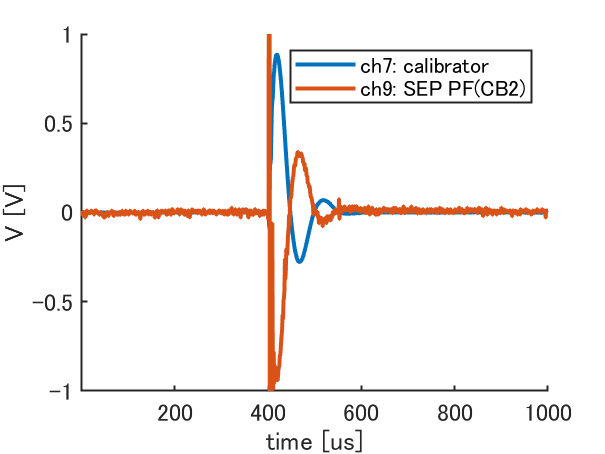

%%%230126のデータを用いたcalibration
%較正器は10kA/V

folder_directory_rogo = getenv('rogo_path');
date=230126;

aquisition_rate=10; %[MHz]
offset=0;
t_start = 1; % us
t_end = 1000; % us
t_start=t_start-offset;t_end=t_end-offset; % set offset
time_step = 1;%0.2; % us; time step of plot; must be an integer times of time step of raw data; larger time step gives faster plotting.
step = aquisition_rate * time_step;
x = t_start * aquisition_rate : step : t_end * aquisition_rate;

upper = 1;%0.6; % upper limit of y axis
lower = -1;%-0.4; % lower limit of y axis

%shot6,ch7:calibrator,ch9:SEP PF(CB2)
shot=6;
[date_str,shot_str,path] = directory_generation_Rogowski(date,shot,folder_directory_rogo);
data1 = readmatrix(path);
data1(:,2:end)=data1(:,2:end)-mean(data1(1:3000,2:end));
channels1=[7,9];
figure
hold on
for i = channels1
    plot(x/aquisition_rate+offset,data1(x,i+2),'LineWidth',2);
end
legend('ch7: calibrator','ch9: SEP PF(CB2)')
ylim([lower upper]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('V [V]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 
hold off


t_calib = 440:500;
t_calib = t_calib(1) * aquisition_rate : step : t_calib(end) * aquisition_rate;
a = data1(t_calib,9);
b = data1(t_calib,11);
b = b(b~=0);
a = a(b~=0);
calibration_9=10.*mean(a./b)

calibration_9 = -8.1687

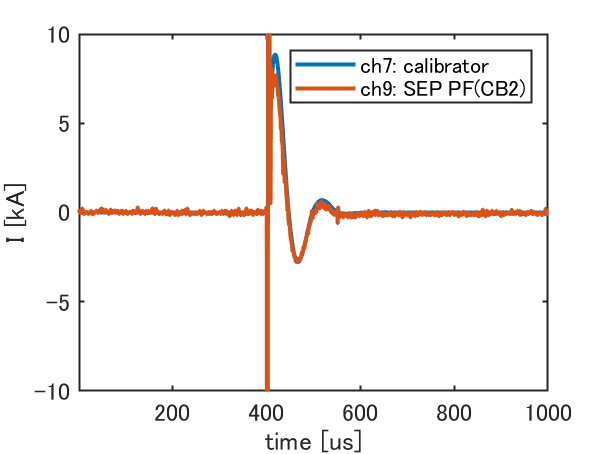


figure
plot(x/aquisition_rate+offset,10.*data1(x,9),'LineWidth',2);
hold on
plot(x/aquisition_rate+offset,calibration_9.*data1(x,11),'LineWidth',2);
hold off
legend('ch7: calibrator','ch9: SEP PF(CB2)')
ylim([-10 10]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('I [kA]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 

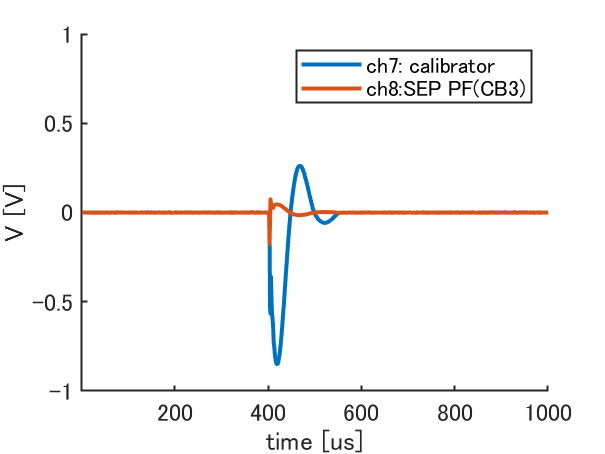


%shot7,ch7:calibrator,ch8:SEP PF(CB3)
shot=7;
[date_str,shot_str,path] = directory_generation_Rogowski(date,shot,folder_directory_rogo);
data2 = readmatrix(path);
data2(:,2:end)=data2(:,2:end)-data2(offset+1,2:end);
channels1=[7,8];
figure
hold on
for i = channels1
    plot(x/aquisition_rate+offset,data2(x,i+2),'LineWidth',2);
end
legend('ch7: calibrator','ch8:SEP PF(CB3)')
ylim([lower upper]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('V [V]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 
hold off


t_calib = 440:490;
t_calib = t_calib(1) * aquisition_rate : step : t_calib(end) * aquisition_rate;
a = data2(t_calib,9);
b = data2(t_calib,10);
b = b(b~=0);
a = a(b~=0);
calibration_8=-10.*mean(a./b)

calibration_8 = 167.6939

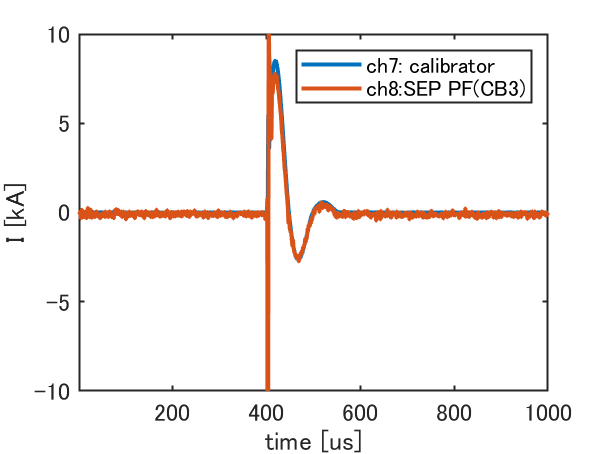


figure
plot(x/aquisition_rate+offset,-10.*data2(x,9),'LineWidth',2);
hold on
plot(x/aquisition_rate+offset,calibration_8.*data2(x,10),'LineWidth',2);
hold off
legend('ch7: calibrator','ch8:SEP PF(CB3)')
ylim([-10 10]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('I [kA]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 

function [date_str,shot_str,data_dir] = directory_generation_Rogowski(date,shot,folder_directory_rogo)
    date_str = num2str(date);
    if shot < 10
        data_dir = [folder_directory_rogo,date_str,'\',date_str,'00',num2str(shot),'.txt'];
        shot_str = ['00',num2str(shot)];
    elseif shot < 100
        data_dir = [folder_directory_rogo,date_str,'\',date_str,'0',num2str(shot),'.txt'];
        shot_str = ['0',num2str(shot)];
    elseif shot < 1000
        data_dir = [folder_directory_rogo,date_str,'\',date_str,num2str(shot),'.txt'];
        shot_str = num2str(shot);
    else
        disp('More than 999 shots! You need some rest!!!');
        return
    end
end